# **BASIC MATH MODELLING **

### **INDUSTRIAL SCARA**

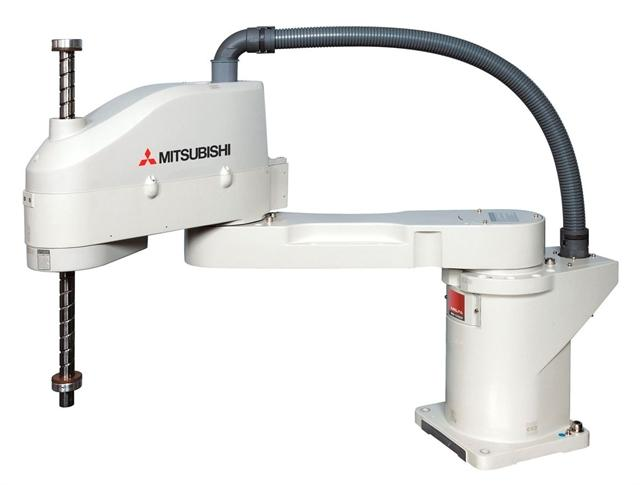

### KNOWN PARAMETERS

% CHOSEN CONFIGURATION --> RRRP
% ALTERNATIVE CONFIGURATION --> RPRR
DOF = 4;
payload = 2; %in kg

op_reach = 20:80; % in cm
shoulder = 350; % in deg
elbow = -100:100; % in deg
wrist = 360; % in deg
robot_ht = 1; % in meters and is same as workspace

% objects: cylinders, cubes, cuboids
max_ht = 10;
tool_speed = 15; % in cm/s

### OTHER PARAMETERS

syms d4;
syms d1;
syms t1;
syms t2;
syms t3;
l3 = 30; % in cm
l2 = 30; % in cm
syms X_dot;
syms Y_dot;
syms Z_dot;
syms t_dot;
syms W_1;
syms W_2;
syms W_3;
syms qdot_1;
syms qdot_2;
syms qdot_3;
syms ddot_4;

### DH PARAMETER TABLE

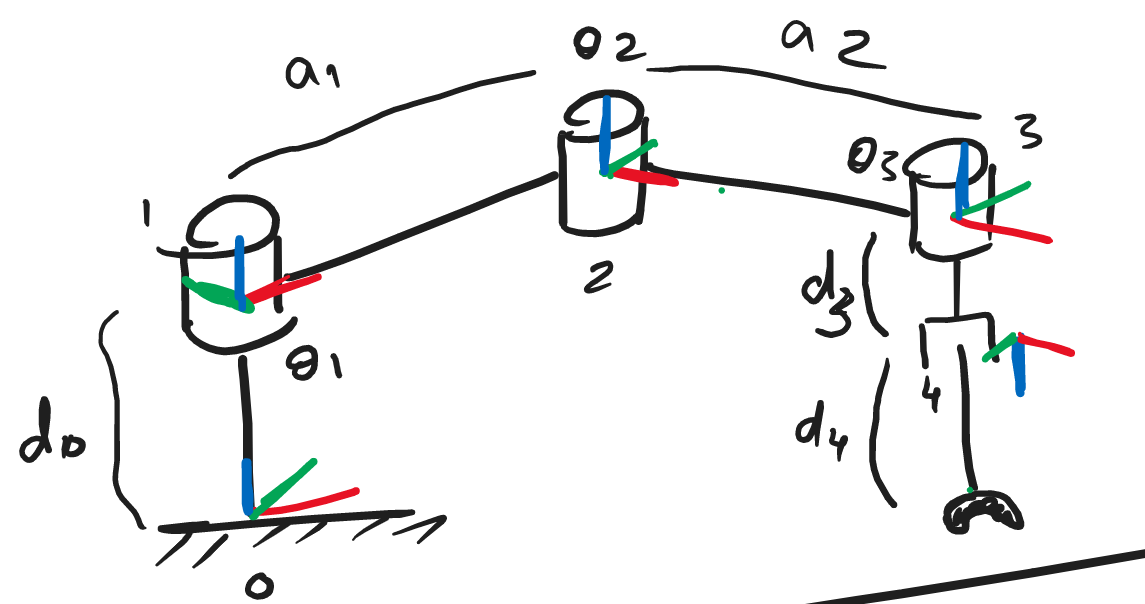

dh1 = [0 0 d1 t1];
dh2 = [l2 0 0 t2];
dh3 = [l3 0 0 t3];
dh4 = [0 180 d4 0];

### FORWARD KINEMATICS

T_0_1 = Transformation_Matrix(dh1);
T_1_2 = Transformation_Matrix(dh2);
T_2_3 = Transformation_Matrix(dh3);
T_3_4 = Transformation_Matrix(dh4);
% Final Transformation
T_0_4 = simplify(T_0_1*T_1_2*T_2_3*T_3_4)

$$T\_0\_4 = \begin{array}{l} \left(\begin{array}{cccc} \sigma_{2} & \sigma_{1} & 0 & 30\,\cos\left(\frac{\pi \,\left(t_{1}+t_{2}\right)}{180}\right)+30\,\sigma_{2}\\ \sigma_{1} & -\sigma_{2} & 0 & 30\,\sin\left(\frac{\pi \,\left(t_{1}+t_{2}\right)}{180}\right)+30\,\sigma_{1}\\ 0 & 0 & -1 & d_{1}+d_{4}\\ 0 & 0 & 0 & 1 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\sin\left(\frac{\pi \,\left(t_{1}+t_{2}+t_{3}\right)}{180}\right)\\ \sigma_{2}=\cos\left(\frac{\pi \,\left(t_{1}+t_{2}+t_{3}\right)}{180}\right) \end{array}$$

### VELOCITY KINEMATICS

%v = J.q_dot
jacobian = eval(Jacobian(T_0_4,t1,t2,t3,d4))

$$jacobian = \begin{array}{l} \left(\begin{array}{cccc} \sigma_{1} & \sigma_{1} & -\frac{\pi \,\sin\left(\frac{\pi \,\left(t_{1}+t_{2}+t_{3}\right)}{180}\right)}{6} & 0\\ \sigma_{2} & \sigma_{2} & \frac{\pi \,\cos\left(\frac{\pi \,\left(t_{1}+t_{2}+t_{3}\right)}{180}\right)}{6} & 0\\ 0 & 0 & 0 & 1\\ 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0\\ \frac{\pi }{180} & \frac{\pi }{180} & \frac{\pi }{180} & 0 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=-\frac{\pi \,\left(\sin\left(\frac{\pi \,\left(t_{1}+t_{2}\right)}{180}\right)+\sin\left(\frac{\pi \,\left(t_{1}+t_{2}+t_{3}\right)}{180}\right)\right)}{6}\\ \sigma_{2}=\frac{\pi \,\left(\cos\left(\frac{\pi \,\left(t_{1}+t_{2}\right)}{180}\right)+\cos\left(\frac{\pi \,\left(t_{1}+t_{2}+t_{3}\right)}{180}\right)\right)}{6} \end{array}$$

q_dot = [qdot_1;qdot_2;qdot_3;ddot_4];
vel = simplify(eval(jacobian*q_dot))

$$vel = \begin{array}{l} \left(\begin{array}{c} -\frac{\pi \,{\mathrm{qdot}}_{1}\,\sigma_{1}}{6}-\frac{\pi \,{\mathrm{qdot}}_{2}\,\sigma_{1}}{6}-\frac{\pi \,{\mathrm{qdot}}_{3}\,\sin\left(\frac{\pi \,\left(t_{1}+t_{2}+t_{3}\right)}{180}\right)}{6}\\ \frac{\pi \,{\mathrm{qdot}}_{1}\,\sigma_{2}}{6}+\frac{\pi \,{\mathrm{qdot}}_{2}\,\sigma_{2}}{6}+\frac{\pi \,{\mathrm{qdot}}_{3}\,\cos\left(\frac{\pi \,\left(t_{1}+t_{2}+t_{3}\right)}{180}\right)}{6}\\ {\mathrm{ddot}}_{4}\\ 0\\ 0\\ \frac{\pi \,\left({\mathrm{qdot}}_{1}+{\mathrm{qdot}}_{2}+{\mathrm{qdot}}_{3}\right)}{180} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\sin\left(\frac{\pi \,\left(t_{1}+t_{2}\right)}{180}\right)+\sin\left(\frac{\pi \,\left(t_{1}+t_{2}+t_{3}\right)}{180}\right)\\ \sigma_{2}=\cos\left(\frac{\pi \,\left(t_{1}+t_{2}\right)}{180}\right)+\cos\left(\frac{\pi \,\left(t_{1}+t_{2}+t_{3}\right)}{180}\right) \end{array}$$



% vel = [X_dot;Y_dot;Z_dot;W_3];
% q_dot = simplify(eval(inverse([jacobian(1:3,:);jacobian(4,:)])*vel))

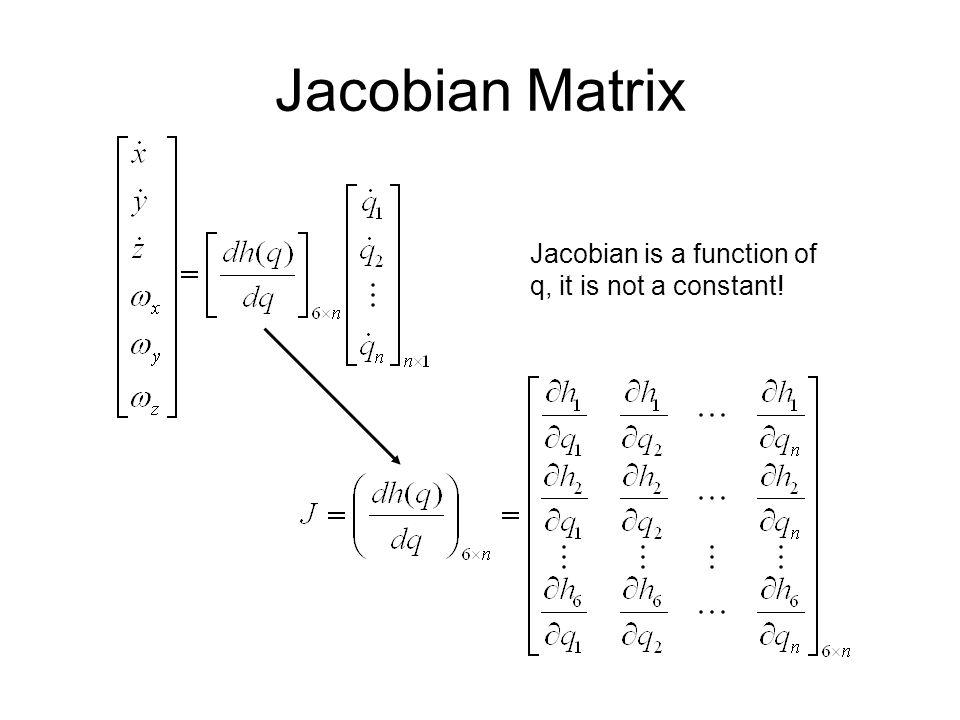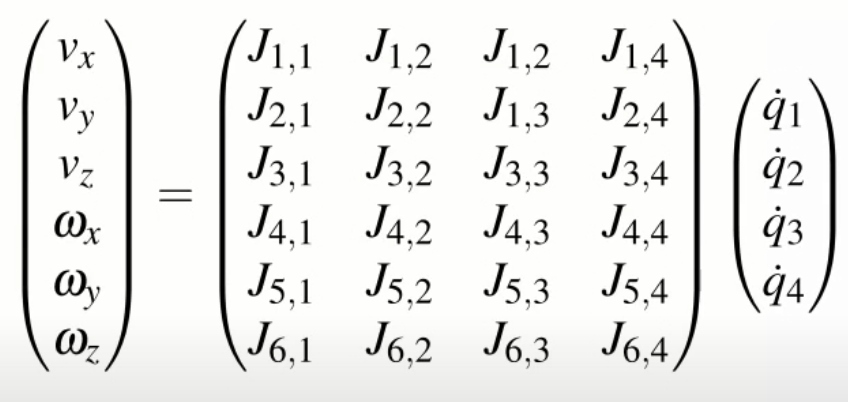

**JACOBIAN FUNCTION**

function jacob = Jacobian(T,t1,t2,t3,d4)
jacob = simplify([Jacobi(T,t1) Jacobi(T,t2) Jacobi(T,t3) Jacobi(T,d4)]);



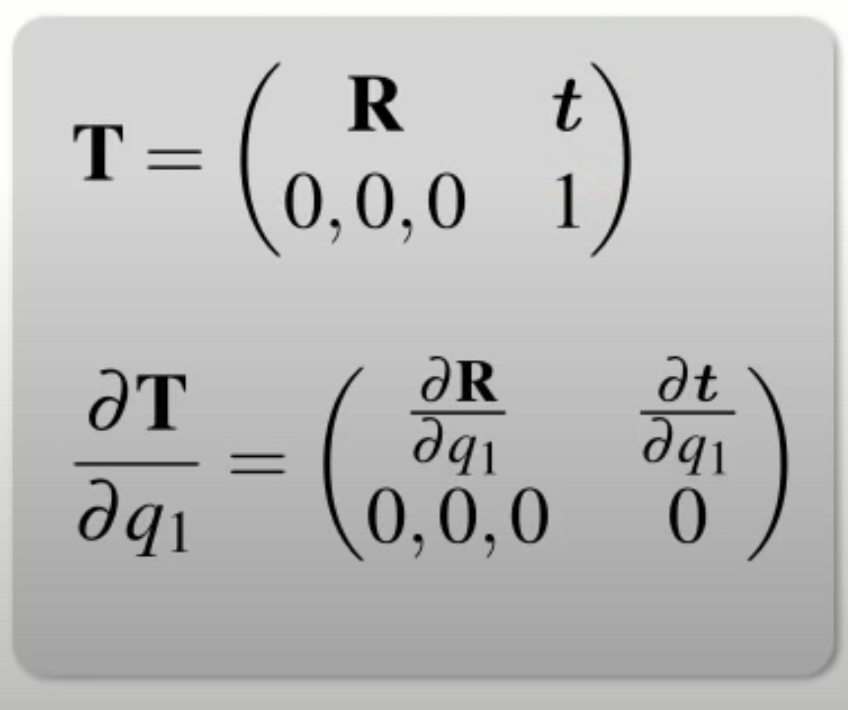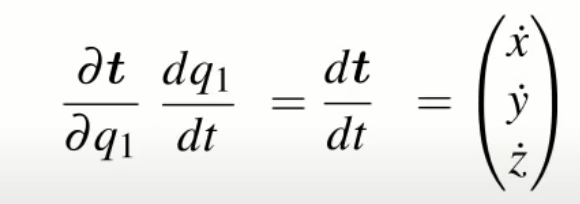-----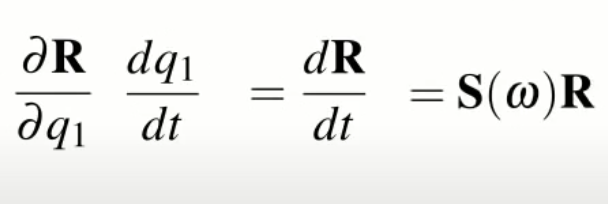

function jacobi = Jacobi(T,q)
% Translation
diff_T_t_i = diff(T,q); % differentiating T matrix wrt q
v_dot = diff_T_t_i(1:3,4);
x_dot = v_dot(1);
y_dot = v_dot(2);
z_dot = v_dot(3);
% Rotation
Ri= T(1:3,1:3);
Ri_diff = diff_T_t_i(1:3,1:3);
omega = Ri_diff*transpose(Ri);
w_1 = omega(3,2);
w_2 = -omega(3,1);
w_3 = omega(2,1);
jacobi = simplify([x_dot;y_dot;z_dot;w_1;w_2;w_3]);
end
end

#### TRANSFORMATION MATRIX FUNCTION

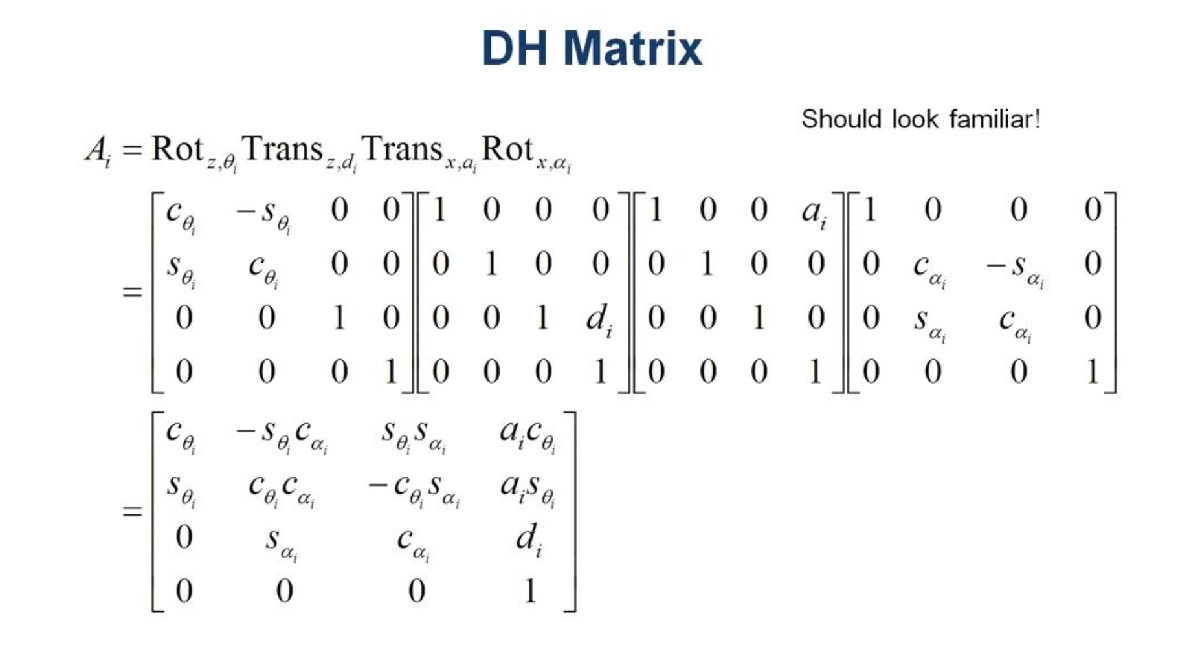

function ti1_i = Transformation_Matrix(dh_row)
ti1_i = [cosd(dh_row(4)) -sind(dh_row(4))*cosd(dh_row(2)) sind(dh_row(4))*sind(dh_row(2)) dh_row(1)*cosd(dh_row(4));
         sind(dh_row(4)) cosd(dh_row(4))*cosd(dh_row(2)) -cosd(dh_row(4))*sind(dh_row(2)) dh_row(1)*sind(dh_row(4));
         0   sind(dh_row(2)) cosd(dh_row(2)) dh_row(3) ;
         0   0   0   1];
end